## **Problem Statement**

Controlling gene expression is critical in maintaining the healthy operation, we can use gene circuit to regulate the target gene. 

This is a demo

par.mu = 10; %%% inducer nM
par.alpha = 0.5;  %%%% 
par.gamma = 2; %%% 
%par.beta = 0.8; %%% C to D repression
par.delta = 0.01;

tspan = 0:0.1:1200;
options = odeset('RelTol',1e-10,'AbsTol',1e-10);
x0 = [0 0 0];  
[t,y0]=ode23s(@(t,x) Base_Model(t,x,par),tspan,x0,options);
y0 

y0 =          0         0         0
    0.9995    0.0250    0.0004
    1.9975    0.0999    0.0029
    2.9923    0.2245    0.0080
    3.9807    0.3985    0.0152
    4.9589    0.6216    0.0232
    5.9237    0.8929    0.0311
    6.8725    1.2119    0.0387
    7.8029    1.5774    0.0459
    8.7128    1.9886    0.0530


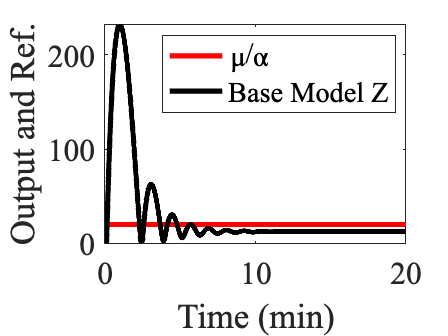

Reference = ones(1,length(t))*par.mu/par.alpha;

figure(1)
plot(t./60,Reference,t./60,y0(:,3),'-k','LineWidth',3)
legend('\mu/\alpha','Base Model Z')
xlabel('Time (min)')
ylabel('Output and Ref.')
set(gca,'FontSize',18)
set(gca,'FontName','Times New Roman')

function dx = Base_Model(t,x,par)

dx = zeros(3,1);

X = x(1); 
A = x(2);
Z = x(3);

dx(1) = par.mu - par.gamma*X*Z - par.delta*X;
dx(2) = par.alpha*X - par.delta*A;
dx(3) = par.alpha*A - par.gamma*X*Z - par.delta*Z ;

end

ODE for the antithetic circuit for gene expression regualtion.


$$$\frac{dX}{dt}=\mu - \gamma*X*Z - \delta*X\\
\frac{dA}{dt} = \alpha*X-\delta*A\\
\frac{dZ}{dt} = \alpha*A - \gamma*X*Z - \delta*Z$$
